%% =========================================================
%  NAV_NEW_GRAPHS.M
%
%  Gráficos de navegação — lêem EXCLUSIVAMENTE do struct RESULTS
%  produzido por run_nav_stats(), SUS, SYS_EVAL, COMP e
%  navigation_performance.
%
%  BLOCOS
%  ──────
%  NAV-2  Performance boxplots T1/T2 + pairwise sig lines
%         (Friedman global sig. E par individual sig.)
%
%  NAV-3  Success rate — barras agrupadas T1|T2 por método
%         + linhas pairwise (Cochran post-hoc students;
%           McNemar interns) lidas de RESULTS.success
%
%  NAV-4  Spider chart System Evaluation — um gráfico por grupo
%         (Students: EM/2D/3D | Interns: EM/3D)
%         8 dimensões, medianas de RESULTS.syseval.<dim>.descriptives
%
%  NAV-5  Spider chart Comparative Ratings — um gráfico por grupo
%         7 dimensões, medianas de RESULTS.comp.<dim>.descriptives
%         NOTA: escala 1-3 (ranking), invertida no gráfico
%               (1=melhor → raio maior)
%
%  NAV-6  Spider chart SUS por item (Q1–Q10) — um gráfico por grupo
%         escala raw 1-5, medianas de SUS.<meth>.items
%
%  PRÉ-REQUISITOS no workspace:
%    RESULTS, SUS, SYS_EVAL, COMP,
%    navigation_performance, stud_idx, int_idx
%% =========================================================

alpha = 0.05;

%% ── Paletas de cores ───────────────────────────────────────
col_nav   = [0.20 0.45 0.72;   % EM  — azul
             0.17 0.63 0.45;   % 2D  — verde
             0.84 0.37 0.12];  % 3D  — laranja
col_nav_2 = col_nav([1 3],:);  % EM + 3D (internos)

colors_t1t2 = [0.23 0.47 0.72;   % EM  T1
               0.60 0.78 0.95;   % EM  T2
               0.17 0.63 0.45;   % 2D  T1
               0.65 0.88 0.72;   % 2D  T2
               0.84 0.37 0.12;   % 3D  T1
               0.97 0.70 0.50];  % 3D  T2

group_idxs   = {stud_idx, int_idx};
group_titles = {'Students (Inexperienced)', 'Interns (Experienced)'};
group_short  = {'students', 'interns'};

continuous_metrics = {'planning_time','puncture_time','distance_to_target','attempts'};
metric_ylabels     = {'Planning Time (s)','Puncture Time (s)',...
                      'Distance to Target (mm)','Number of Attempts'};

%% =========================================================
%  NAV-2 — Performance boxplots T1/T2 + pairwise sig lines
%
%  Boxplots:  navigation_performance.(met)
%  T1 vs T2:  RESULTS.performance.(met).t1vt2.(meth).(group).p
%  Friedman:  RESULTS.performance.(met).friedman_students.p + .posthoc
%  Wilcoxon:  RESULTS.performance.(met).wilcoxon_interns.p
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' NAV-2 — PERFORMANCE BOXPLOTS + PAIRWISE\n');

 NAV-2 — PERFORMANCE BOXPLOTS + PAIRWISE


fprintf('==================================================\n');

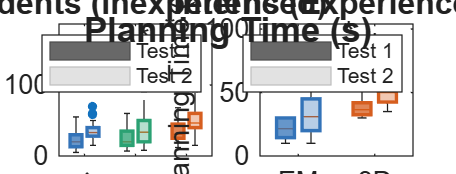

Figura guardada: nav_boxplot_planning_time_pairwise.pdf


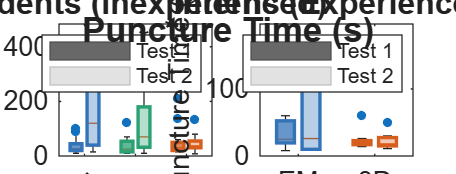

Figura guardada: nav_boxplot_puncture_time_pairwise.pdf


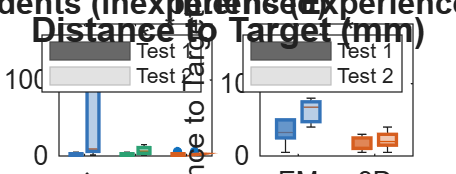

Figura guardada: nav_boxplot_distance_to_target_pairwise.pdf


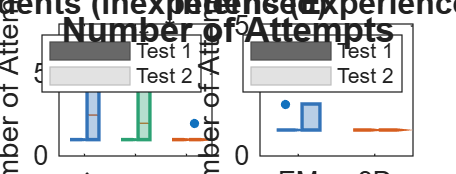

Figura guardada: nav_boxplot_attempts_pairwise.pdf



%  col_ord: índices na matriz [N x 6]
%    x2d_t1=1, x2d_t2=2, x3d_t1=3, x3d_t2=4, em_t1=5, em_t2=6
layout(1).xpos       = [1 2 4 5 7 8];
layout(1).xmid       = [1.5 4.5 7.5];
layout(1).col_ord    = [5 6 1 2 3 4];
layout(1).xlims      = [0 9];
layout(1).xtick      = [1.5 4.5 7.5];
layout(1).xlbl       = {'EM','2D','3D'};
layout(1).n_meth     = 3;
layout(1).pairs_t12  = [1 2; 3 4; 5 6];
layout(1).t12_meths  = {'em','x2d','x3d'};
layout(1).t12_grp    = {'students','students','students'};

layout(2).xpos       = [1 2 4 5];
layout(2).xmid       = [1.5 4.5];
layout(2).col_ord    = [5 6 3 4];
layout(2).xlims      = [0 6];
layout(2).xtick      = [1.5 4.5];
layout(2).xlbl       = {'EM','3D'};
layout(2).n_meth     = 2;
layout(2).pairs_t12  = [1 2; 3 4];
layout(2).t12_meths  = {'em','x3d'};
layout(2).t12_grp    = {'interns','interns'};

for mi = 1:numel(continuous_metrics)
    met = continuous_metrics{mi};
    X   = navigation_performance.(met);
    R   = RESULTS.performance.(met);

    fig = figure('Name',sprintf('Nav_%s_pairwise',met), ...
        'Units','centimeters','Position',[2 2 26 10],'Color','white');

    for gi = 1:2
        idx = group_idxs{gi};
        L   = layout(gi);
        ax  = subplot(1,2,gi);
        hold(ax,'on'); box(ax,'on');

        % 1. Boxplots
        % Cor derivada do método (ceil(c/2)) e não da posição sequencial,
        % para garantir consistência entre Students e Interns.
        % col_nav_gi: mapeamento método→cor para este grupo
        if gi == 1
            col_nav_gi = col_nav;           % método 1=EM, 2=2D, 3=3D
        else
            col_nav_gi = col_nav([1 3],:);  % método 1=EM, 2=3D
        end
        all_vals = [];
        for c = 1:numel(L.xpos)
            col_d = X(idx, L.col_ord(c));
            col_d = col_d(~isnan(col_d));
            all_vals = [all_vals; col_d]; %#ok<AGROW>
            if isempty(col_d), continue; end
            bp    = boxplot(ax, col_d, 'Positions', L.xpos(c), 'Widths', 0.7, ...
                'Symbol','o','OutlierSize',3);
            h_box = findobj(bp,'Tag','Box');
            meth_idx  = ceil(c/2);                    % 1=EM, 2=2D/3D, 3=3D (students)
            base_col  = col_nav_gi(meth_idx,:);
            is_t1     = mod(c,2) == 1;                % ímpares = T1, pares = T2
            fa        = 0.75 * is_t1 + 0.35 * ~is_t1; % T1 mais sólido, T2 mais transparente
            patch(ax, get(h_box,'XData'), get(h_box,'YData'), base_col, ...
                'FaceAlpha',fa,'EdgeColor',base_col,'LineWidth',1.3);
        end
        if isempty(all_vals), continue; end
        y_data = max(all_vals);
        gap    = y_data * 0.09;

        % 2. Linhas T1 vs T2
        n_t12 = size(L.pairs_t12,1);
        y_t12 = zeros(n_t12,1);
        for pi = 1:n_t12
            mkey  = L.t12_meths{pi};
            grp   = L.t12_grp{pi};
            p_t12 = NaN;
            if isfield(R,'t1vt2') && isfield(R.t1vt2,mkey) && ...
               isfield(R.t1vt2.(mkey),grp) && isfield(R.t1vt2.(mkey).(grp),'p')
                p_t12 = min(R.t1vt2.(mkey).(grp).p * n_t12, 1);
            end
            if isnan(p_t12) || p_t12 >= alpha, continue; end
            x1_l = L.xpos(L.pairs_t12(pi,1));
            x2_l = L.xpos(L.pairs_t12(pi,2));
            y_line = y_data + gap;
            y_t12(pi) = y_line;
            tk = gap * 0.25;
            line(ax,[x1_l x1_l x2_l x2_l],[y_line-tk y_line y_line y_line-tk], ...
                'Color','k','LineWidth',1.2,'Clipping','off');
            text(ax,(x1_l+x2_l)/2, y_line+tk*0.3, sig_star(p_t12), ...
                'HorizontalAlignment','center','VerticalAlignment','bottom', ...
                'FontSize',10,'FontWeight','bold','Clipping','off');
        end

        % 3. Linhas entre métodos — posicionadas pelas caixas do teste
        %    em que o efeito foi detectado (T1 e/ou T2 separados).
        %    Lógica por grupo:
        %    Students: verificar friedman_students_t1 e friedman_students_t2
        %              e respetivos posthoc. Para cada par sig. no posthoc do
        %              teste X, a linha vai de xpos(T_X do método m1) a
        %              xpos(T_X do método m2).
        %    Interns:  verificar wilcoxon_interns_t1 e wilcoxon_interns_t2.
        %
        %  Mapeamento xpos por método e teste (layout(gi)):
        %    Students: EM_T1=xpos(1), EM_T2=xpos(2),
        %              2D_T1=xpos(3), 2D_T2=xpos(4),
        %              3D_T1=xpos(5), 3D_T2=xpos(6)
        %    Interns:  EM_T1=xpos(1), EM_T2=xpos(2),
        %              3D_T1=xpos(3), 3D_T2=xpos(4)
        %  t_box_idx(m, t) → índice em L.xpos para método m, teste t (1 ou 2)
        t_box_idx = @(m,t) (m-1)*2 + t;   % m=método (1-based), t=1 ou 2

        y_above = max([y_data; y_t12]) + gap*1.5;
        y_cur   = y_above;

        if gi == 1   % Students
            fr_fields  = {'friedman_students_t1','friedman_students_t2'};
            t_labels   = {1, 2};   % índice de teste para t_box_idx
            % Recolher todos os pares sig. por teste, sem duplicar y_cur
            for ti = 1:2
                ff = fr_fields{ti};
                t  = t_labels{ti};
                if ~isfield(R,ff) || ~isfield(R.(ff),'p'), continue; end
                if R.(ff).p >= alpha || ~isfield(R.(ff),'posthoc'), continue; end
                ph = R.(ff).posthoc;
                for pi = 1:numel(ph)
                    p_pair = ph(pi).p_bonf;
                    if isnan(p_pair) || p_pair >= alpha, continue; end
                    m1 = cond_label_to_idx(ph(pi).cond1);
                    m2 = cond_label_to_idx(ph(pi).cond2);
                    if m1==0 || m2==0, continue; end
                    % x posições das caixas do teste t para os métodos m1 e m2
                    x1_m = L.xpos(t_box_idx(m1,t));
                    x2_m = L.xpos(t_box_idx(m2,t));
                    draw_sig_bracket(ax, x1_m, x2_m, y_cur, gap, p_pair);
                    y_cur = y_cur + gap*1.4;
                end
            end

        else   % Interns — verificar t1 e t2 separados
            wi_fields = {'wilcoxon_interns_t1','wilcoxon_interns_t2'};
            t_labels  = {1, 2};
            for ti = 1:2
                ff = wi_fields{ti};
                t  = t_labels{ti};
                if ~isfield(R,ff) || ~isfield(R.(ff),'p'), continue; end
                p_wi = R.(ff).p;
                if isnan(p_wi) || p_wi >= alpha, continue; end
                x1_m = L.xpos(t_box_idx(1,t));   % EM
                x2_m = L.xpos(t_box_idx(2,t));   % 3D
                draw_sig_bracket(ax, x1_m, x2_m, y_cur, gap, p_wi);
                y_cur = y_cur + gap*1.4;
            end
        end

        % 4. Axes
        ylim(ax,[0, y_cur + gap*1.5]);
        xlim(ax, L.xlims);
        set(ax,'XTick',L.xtick,'XTickLabel',L.xlbl,'FontSize',10);
        xlabel(ax,'Method','FontSize',11);
        ylabel(ax,metric_ylabels{mi},'FontSize',11);
        title(ax,group_titles{gi},'FontSize',12,'FontWeight','bold');
        lh1 = patch(ax,NaN,NaN,[0.30 0.30 0.30],'FaceAlpha',0.85,'EdgeColor',[0.30 0.30 0.30]);
        lh2 = patch(ax,NaN,NaN,[0.75 0.75 0.75],'FaceAlpha',0.45,'EdgeColor',[0.75 0.75 0.75]);
        legend(ax,[lh1 lh2],{'Test 1','Test 2'},'Location','northeast','FontSize',8);
    end

    sgtitle(fig,metric_ylabels{mi},'FontSize',13,'FontWeight','bold');
    exportgraphics(fig,sprintf('nav_boxplot_%s_pairwise.pdf',met), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: nav_boxplot_%s_pairwise.pdf\n',met);
end



%% =========================================================
%  NAV-3 — Success rate — barras agrupadas T1|T2 + pairwise
%
%  Barras:  navigation_performance.success
%  T1 vs T2 pairwise: RESULTS.success.cochranq_students.{t1/t2}.posthoc
%                     RESULTS.success.mcnemar_interns.{t1/t2}.p
%  Between-method:    RESULTS.success.cochranq_students.global.posthoc
%                     RESULTS.success.mcnemar_interns.global.p
%
%  Layout: uma figura por grupo (Students | Interns)
%  Barras: T1 = cor sólida, T2 = transparente (igual ao antigo)
%  Linhas pairwise: entre métodos (global) e T1 vs T2 (dentro método)
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' NAV-3 — SUCCESS RATE BARRAS + PAIRWISE\n');

 NAV-3 — SUCCESS RATE BARRAS + PAIRWISE


fprintf('==================================================\n');

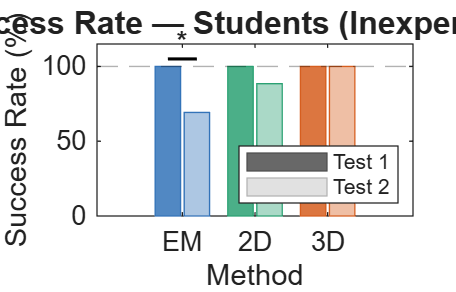

Figura guardada: nav_success_students.pdf


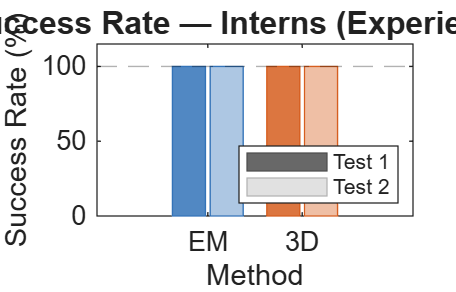

Figura guardada: nav_success_interns.pdf


 
X_suc        = navigation_performance.success;
nav_suc_cols = {[5 6],[1 2],[3 4]};   % EM, 2D, 3D (T1,T2)
RS_suc       = RESULTS.success;
 
for gi = 1:2
    idx = group_idxs{gi};
 
    fig = figure('Name',sprintf('Nav_success_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 14 9],'Color','white');
    ax  = axes(fig); hold(ax,'on'); box(ax,'on');
 
    if gi == 1
        n_meth   = 3;
        meth_lbl = {'EM','2D','3D'};
    else
        n_meth   = 2;
        meth_lbl = {'EM','3D'};
        nav_suc_cols_gi = {[5 6],[3 4]};   % EM, 3D para internos
    end
 
    % Mapeamento cor → índice correcto da paleta por grupo
    if gi == 1
        col_suc = col_nav;           % m=1→EM azul, m=2→2D verde, m=3→3D laranja
    else
        col_suc = col_nav([1 3],:);  % m=1→EM azul, m=2→3D laranja
    end
 
    bar_tops = zeros(n_meth, 2);   % [método x T1/T2] — para posicionar linhas
 
    for m = 1:n_meth
        if gi == 1
            cols = nav_suc_cols{m};
        else
            cols = nav_suc_cols_gi{m};
        end
        c1 = X_suc(idx, cols(1));
        c2 = X_suc(idx, cols(2));
        n1 = sum(~isnan(c1)); n2 = sum(~isnan(c2));
        p1 = 100 * sum(c1(~isnan(c1))) / n1;
        p2 = 100 * sum(c2(~isnan(c2))) / n2;
        xb = [m-0.2, m+0.2];
        b1 = bar(ax,xb(1),p1,0.35); hold(ax,'on');
        b2 = bar(ax,xb(2),p2,0.35);
        b1.FaceColor = col_suc(m,:); b1.FaceAlpha = 0.85; b1.EdgeColor = col_suc(m,:);
        b2.FaceColor = col_suc(m,:); b2.FaceAlpha = 0.40; b2.EdgeColor = col_suc(m,:);
        bar_tops(m,1) = p1;
        bar_tops(m,2) = p2;
    end
 
    y_max = max(bar_tops(:));
    gap   = 5;   % unidade fixa em % para barras binárias
 
    % ── Linhas T1 vs T2 dentro de cada método ────────────────
    % Para Students: usar posthoc do cochranq t1/t2? Não — T1vsT2 dentro de
    % um método é McNemar individual. O RESULTS.success não armazena isso
    % directamente. Calculamos do RESULTS.success.cochranq_students usando
    % o campo posthoc em t1 vs t2 separados NÃO existe.
    % → Usar RESULTS.success.cochranq_students.t1 e .t2 col_sums para
    %   reconstruir a comparação directa, ou simplesmente calcular McNemar
    %   on-the-fly com os dados (único caso em que lemos directamente os dados,
    %   porque o RESULTS não armazena T1vsT2 within-method para success).
    y_t12_top = y_max;
    for m = 1:n_meth
        if gi == 1
            c1 = X_suc(idx, nav_suc_cols{m}(1));
            c2 = X_suc(idx, nav_suc_cols{m}(2));
        else
            c1 = X_suc(idx, nav_suc_cols_gi{m}(1));
            c2 = X_suc(idx, nav_suc_cols_gi{m}(2));
        end
        valid = ~isnan(c1) & ~isnan(c2);
        b_d = sum(c1(valid)==1 & c2(valid)==0);
        c_d = sum(c1(valid)==0 & c2(valid)==1);
        if (b_d+c_d) > 0
            chi2_mc = (abs(b_d-c_d)-1)^2 / (b_d+c_d);
            p_mc    = 1 - chi2cdf(chi2_mc,1);
        else
            p_mc = 1;
        end
        p_bonf = min(p_mc * n_meth, 1);
        if p_bonf < alpha
            y_line = y_t12_top + gap;
            y_t12_top = y_line;
            tk = gap * 0.4;
            line(ax,[m-0.2 m+0.2],[y_line y_line],'Color','k','LineWidth',1.2,'Clipping','off');
            text(ax,m, y_line+tk*0.5, sig_star(p_bonf), ...
                'HorizontalAlignment','center','VerticalAlignment','bottom', ...
                'FontSize',10,'FontWeight','bold','Clipping','off');
        end
    end
 
    % ── Linhas entre métodos (global success) ────────────────
    y_between = y_t12_top + gap*1.5;
 
    if gi == 1
        % Students — Cochran Q global posthoc
        if isfield(RS_suc,'cochranq_students') && ...
           isfield(RS_suc.cochranq_students,'global') && ...
           RS_suc.cochranq_students.global.p < alpha && ...
           isfield(RS_suc.cochranq_students.global,'posthoc')
            ph = RS_suc.cochranq_students.global.posthoc;
            for pi = 1:numel(ph)
                p_pair = ph(pi).p_bonf;
                if isnan(p_pair) || p_pair >= alpha, continue; end
                m1 = cond_label_to_idx(ph(pi).cond1);
                m2 = cond_label_to_idx(ph(pi).cond2);
                if m1==0 || m2==0, continue; end
                draw_sig_bracket(ax, m1, m2, y_between, gap, p_pair);
                y_between = y_between + gap*1.6;
            end
        end
    else
        % Interns — McNemar global
        if isfield(RS_suc,'mcnemar_interns') && ...
           isfield(RS_suc.mcnemar_interns,'global') && ...
           isfield(RS_suc.mcnemar_interns.global,'p')
            p_mn = RS_suc.mcnemar_interns.global.p;
            if ~isnan(p_mn) && p_mn < alpha
                draw_sig_bracket(ax, 1, 2, y_between, gap, p_mn);
                y_between = y_between + gap*1.6;
            end
        end
    end
 
    ylim(ax,[0, min(y_between + gap*2, 115)]);
    set(ax,'XTick',1:n_meth,'XTickLabel',meth_lbl,'FontSize',10);
    xlabel(ax,'Method','FontSize',11);
    ylabel(ax,'Success Rate (%)','FontSize',11);
    title(ax,sprintf('Success Rate — %s',group_titles{gi}), ...
        'FontSize',12,'FontWeight','bold');
    yline(ax,100,'--k','Alpha',0.3);
 
    p1h = patch(ax,NaN,NaN,[0.3 0.3 0.3],'FaceAlpha',0.85,'EdgeColor',[0.3 0.3 0.3]);
    p2h = patch(ax,NaN,NaN,[0.7 0.7 0.7],'FaceAlpha',0.40,'EdgeColor',[0.7 0.7 0.7]);
    legend(ax,[p1h p2h],{'Test 1','Test 2'},'Location','southeast','FontSize',8);
 
    exportgraphics(fig,sprintf('nav_success_%s.pdf',group_short{gi}), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: nav_success_%s.pdf\n',group_short{gi});
end

 
 
%% =========================================================
%  NAV-3b — SUS Score boxplot + sig lines
%
%  Students: Friedman (EM vs 2D vs 3D) + posthoc Bonferroni
%            RESULTS.sus.score.ranova_students (RM-ANOVA ou Friedman)
%            Fallback: recalcular Friedman dos dados SUS
%  Interns:  Wilcoxon EM vs 3D
%            RESULTS.sus.score.paired_t_interns ou wilcoxon equivalente
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' NAV-3b — SUS SCORE BOXPLOT + SIG LINES\n');

 NAV-3b — SUS SCORE BOXPLOT + SIG LINES


fprintf('==================================================\n');

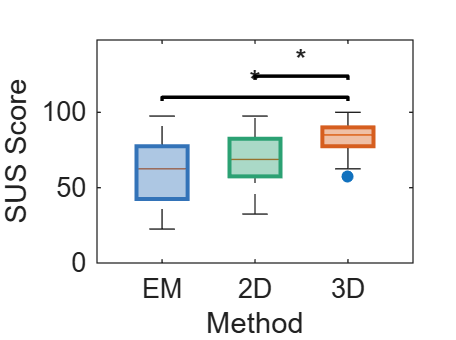

Figura guardada: nav_SUS_score_students.pdf


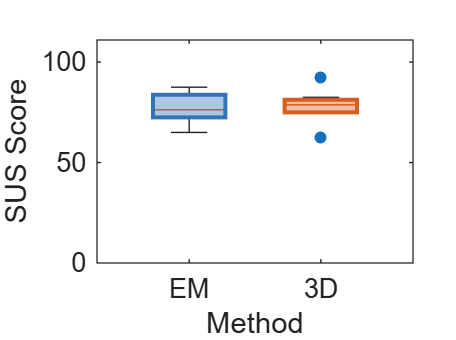

Figura guardada: nav_SUS_score_interns.pdf



for gi = 1:2
    idx = group_idxs{gi};

    fig = figure('Name',sprintf('Nav_SUS_score_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 12 9],'Color','white');
    ax = axes(fig); hold(ax,'on'); box(ax,'on');

    if gi == 1
        % Students: 3 métodos
        D      = [SUS.em.score(idx), SUS.x2d.score(idx), SUS.x3d.score(idx)];
        k      = 3;
        xlbls  = {'EM','2D','3D'};
        colors = col_nav;
        xlims  = [0.3 3.7];

        % Boxplots
        all_v = [];
        for m = 1:k
            col_d = D(:,m); col_d = col_d(~isnan(col_d));
            all_v = [all_v; col_d]; %#ok<AGROW>
            if isempty(col_d), continue; end
            bp = boxplot(ax,col_d,'Positions',m,'Widths',0.55,'Symbol','o','OutlierSize',4);
            h  = findobj(bp,'Tag','Box');
            patch(ax,get(h,'XData'),get(h,'YData'),colors(m,:), ...
                'FaceAlpha',0.4,'EdgeColor',colors(m,:),'LineWidth',1.5);
        end
        y_data = max(all_v);
        gap    = y_data * 0.10;
        y_cur  = y_data + gap;

        % Friedman + posthoc (calcular on-the-fly dos dados — mais fiável)
        D_clean = D(all(~isnan(D),2),:);
        fr_p = 1;
        if size(D_clean,1) >= 5
            try; fr_p = friedman(D_clean,1,'off'); catch; fr_p=1; end
        end
        if fr_p < alpha
            pairs = nchoosek(1:k,2); np = size(pairs,1);
            for pi = 1:np
                c1 = pairs(pi,1); c2 = pairs(pi,2);
                [p_r,~,~] = signrank(D_clean(:,c1),D_clean(:,c2),'method','exact');
                p_b = min(p_r*np,1);
                if p_b >= alpha, continue; end
                draw_sig_bracket(ax, c1, c2, y_cur, gap, p_b);
                y_cur = y_cur + gap*1.4;
            end
        end

    else
        % Interns: EM vs 3D
        D      = [SUS.em.score(idx), SUS.x3d.score(idx)];
        k      = 2;
        xlbls  = {'EM','3D'};
        colors = col_nav([1 3],:);
        xlims  = [0.3 2.7];

        all_v = [];
        for m = 1:k
            col_d = D(:,m); col_d = col_d(~isnan(col_d));
            all_v = [all_v; col_d]; %#ok<AGROW>
            if isempty(col_d), continue; end
            bp = boxplot(ax,col_d,'Positions',m,'Widths',0.55,'Symbol','o','OutlierSize',4);
            h  = findobj(bp,'Tag','Box');
            patch(ax,get(h,'XData'),get(h,'YData'),colors(m,:), ...
                'FaceAlpha',0.4,'EdgeColor',colors(m,:),'LineWidth',1.5);
        end
        y_data = max(all_v);
        gap    = y_data * 0.10;
        y_cur  = y_data + gap;

        % Wilcoxon signed-rank
        valid = ~isnan(D(:,1)) & ~isnan(D(:,2));
        if sum(valid) >= 5
            [p_w,~,~] = signrank(D(valid,1),D(valid,2),'method','exact');
            if p_w < alpha
                draw_sig_bracket(ax, 1, 2, y_cur, gap, p_w);
                y_cur = y_cur + gap*1.4;
            end
        end
    end

    ylim(ax,[0, y_cur + gap]);
    xlim(ax, xlims);
    set(ax,'XTick',1:k,'XTickLabel',xlbls,'FontSize',10);
    xlabel(ax,'Method','FontSize',11);
    ylabel(ax,'SUS Score','FontSize',11);
  

    exportgraphics(fig,sprintf('nav_SUS_score_%s.pdf',group_short{gi}), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: nav_SUS_score_%s.pdf\n',group_short{gi});
end



%% =========================================================
%  NAV-4 — Spider chart System Evaluation — um gráfico por grupo
%  Abordagem idêntica ao draw_radar original (que funcionava).
%  Students: EM / 2D / 3D  |  Interns: EM / 3D (cores fixas da paleta)
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' NAV-4 — SPIDER CHART SYSTEM EVALUATION\n');

 NAV-4 — SPIDER CHART SYSTEM EVALUATION


fprintf('==================================================\n');

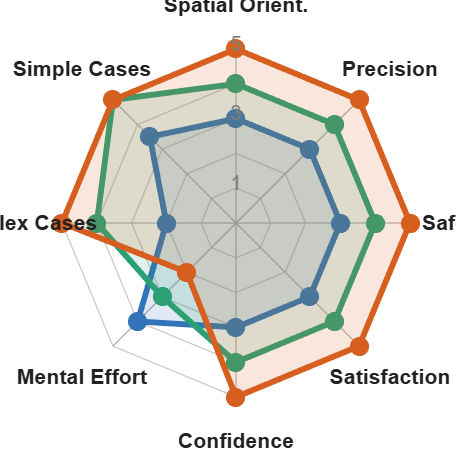

Figura guardada: nav_syseval_spider_students.pdf


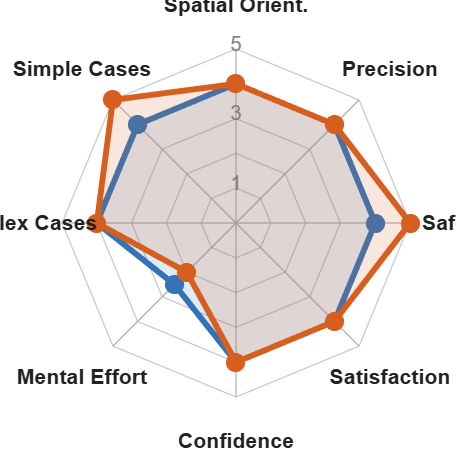

Figura guardada: nav_syseval_spider_interns.pdf



sys_dims_nav = {'safe','precise','spatial_orientation','simple_cases',...
                'complex_cases','mental_effort','confidence','satisfaction'};
sys_lbl_nav  = {'Safety','Precision','Spatial Orient.','Simple Cases',...
                'Complex Cases','Mental Effort','Confidence','Satisfaction'};

for gi = 1:2
    idx     = group_idxs{gi};
    nd      = numel(sys_dims_nav);
    grp_key = group_short{gi};   % 'students' ou 'interns'

    if gi == 1
        keys    = {'em','x2d','x3d'};
        colors  = col_nav;             % linhas 1,2,3 → EM azul, 2D verde, 3D laranja
        leg_lbl = {'EM','2D','3D'};
    else
        keys    = {'em','x3d'};
        colors  = col_nav([1 3],:);    % linha 1→EM azul, linha 2→3D laranja
        leg_lbl = {'EM','3D'};
    end

    D = zeros(nd, numel(keys));
    for d = 1:nd
        for m = 1:numel(keys)
            try
                D(d,m) = RESULTS.syseval.(sys_dims_nav{d}).descriptives.(grp_key).(keys{m}).median;
            catch
                D(d,m) = NaN;
            end
        end
    end

    fig = figure('Name',sprintf('Nav_syseval_spider_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 13 13],'Color','white');
    ax = axes(fig); hold(ax,'on');
    h_lines = draw_radar_nav(ax, D, sys_lbl_nav, colors, 5);

   % legend(ax, h_lines, leg_lbl, 'Location','southoutside', ...
    %    'Orientation','horizontal','FontSize',10,'Box','off');


    fname = sprintf('nav_syseval_spider_%s.pdf',group_short{gi});
    exportgraphics(fig,fname,'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: %s\n',fname);
end



%% =========================================================
%  NAV-5 — Spider chart Comparative Ratings — um gráfico por grupo
%  Escala 1-3 (ranking). Plotado directamente (1=menor raio, 3=maior).
%  Nota: nos comparative ratings, valor MENOR = melhor método (rank 1).
%  Por isso usamos a escala raw — a legenda indica isso.
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' NAV-5 — SPIDER CHART COMPARATIVE RATINGS\n');

 NAV-5 — SPIDER CHART COMPARATIVE RATINGS


fprintf('==================================================\n');

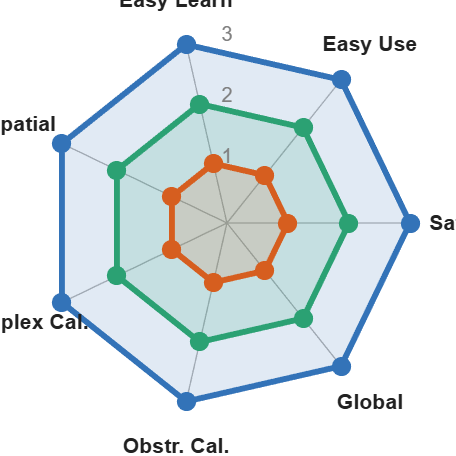

Figura guardada: nav_comp_spider_students.pdf


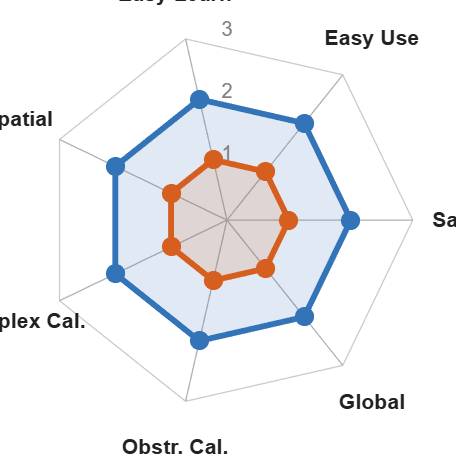

Figura guardada: nav_comp_spider_interns.pdf



comp_dims_nav = {'safer','easy_use','easy_learn','spatial',...
                 'complex_calixes','obstructed_calixes','global'};
comp_lbl_nav  = {'Safer','Easy Use','Easy Learn','Spatial',...
                 'Complex Cal.','Obstr. Cal.','Global'};

for gi = 1:2
    idx     = group_idxs{gi};
    nd      = numel(comp_dims_nav);
    grp_key = group_short{gi};

    if gi == 1
        keys    = {'em','x2d','x3d'};
        colors  = col_nav;
        leg_lbl = {'EM','2D','3D'};
    else
        keys    = {'em','x3d'};
        colors  = col_nav([1 3],:);
        leg_lbl = {'EM','3D'};
    end

    D = zeros(nd, numel(keys));
    for d = 1:nd
        for m = 1:numel(keys)
            try
                D(d,m) = RESULTS.comp.(comp_dims_nav{d}).descriptives.(grp_key).(keys{m}).median;
            catch
                D(d,m) = NaN;
            end
        end
    end

    fig = figure('Name',sprintf('Nav_comp_spider_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 13 13],'Color','white');
    ax = axes(fig); hold(ax,'on');
    h_lines = draw_radar_nav(ax, D, comp_lbl_nav, colors, 3);

    %legend(ax, h_lines, leg_lbl, 'Location','southoutside', ...
     %   'Orientation','horizontal','FontSize',10,'Box','off');


    fname = sprintf('nav_comp_spider_%s.pdf',group_short{gi});
    exportgraphics(fig,fname,'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: %s\n',fname);
end


%% =========================================================
%  NAV-5b — Comparative Ratings: barras agrupadas
%  % participantes que selecionou cada método como rank 1 (melhor)
%  Uma figura por grupo, todas as dimensões no mesmo gráfico.
%  Dados: COMP.<meth>.<dim>(idx) — valor 1 = método escolhido como melhor
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' NAV-5b — COMP RATINGS GROUPED BAR CHART\n');

 NAV-5b — COMP RATINGS GROUPED BAR CHART


fprintf('==================================================\n');

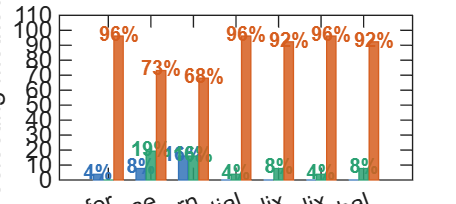

Figura guardada: nav_comp_bar_students.pdf


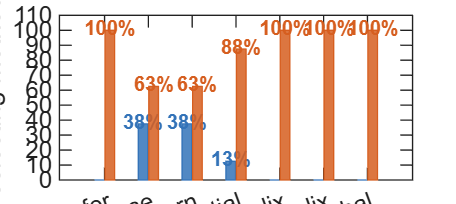

Figura guardada: nav_comp_bar_interns.pdf



comp_lbl_short = {'Safer','Easy use','Easy learn','Spatial',...
    'Complx calix','Obstr. calix','Global'};

for gi = 1:2
    idx = group_idxs{gi};
    n   = sum(idx);

    if gi == 1
        keys    = {'em','x2d','x3d'};
        colors  = col_nav;
        leg_lbl = {'EM','2D','3D'};
    else
        keys    = {'em','x3d'};
        colors  = col_nav([1 3],:);
        leg_lbl = {'EM','3D'};
    end

    nm = numel(keys);
    nd = numel(comp_dims_nav);

    % Matriz [nd x nm]: % participantes com rank=1 em cada dimensão
    pct = zeros(nd, nm);
    for d = 1:nd
        for m = 1:nm
            try
                vals = COMP.(keys{m}).(comp_dims_nav{d})(idx);
                pct(d,m) = 100 * sum(vals(~isnan(vals)) == 1) / sum(~isnan(vals));
            catch
                pct(d,m) = 0;
            end
        end
    end

    fig = figure('Name',sprintf('Nav_comp_bar_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 20 9],'Color','white');
    ax = axes(fig); hold(ax,'on'); box(ax,'on');

    bar_w   = 0.22;
    offsets = linspace(-(nm-1)/2, (nm-1)/2, nm) * (bar_w + 0.02);

    for m = 1:nm
        xb = (1:nd) + offsets(m);
        bh = bar(ax, xb, pct(:,m), bar_w);
        bh.FaceColor = colors(m,:);
        bh.EdgeColor = colors(m,:);
        bh.FaceAlpha = 0.85;

        % Labels de percentagem em cima de cada barra (só se > 0)
        for d = 1:nd
            if pct(d,m) > 0
                text(ax, xb(d), pct(d,m) + 1.5, sprintf('%g%%', round(pct(d,m))), ...
                    'HorizontalAlignment','center','FontSize',7.5, ...
                    'Color', colors(m,:), 'FontWeight','bold');
            end
        end
    end

    ylim(ax,[0 110]);
    set(ax,'XTick',1:nd,'XTickLabel',comp_lbl_short,'FontSize',9, ...
        'XTickLabelRotation',20);
    ylabel(ax,'Participants selecting method as best (%)','FontSize',10);
   %% title(ax,sprintf('Comparative Ratings — %s',group_titles{gi}), ...
     %   'FontSize',12,'FontWeight','bold');
    %legend(ax, leg_lbl,'Location','northeast','FontSize',9,'Box','off');

    fname = sprintf('nav_comp_bar_%s.pdf',group_short{gi});
    exportgraphics(fig,fname,'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: %s\n',fname);
end


%% =========================================================
%  NAV-6 — Spider chart SUS por item (Q1–Q10)
%  Medianas raw (escala 1-5): SUS.<meth>.items(idx,1:10)
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' NAV-6 — SPIDER CHART SUS POR ITEM\n');

 NAV-6 — SPIDER CHART SUS POR ITEM


fprintf('==================================================\n');

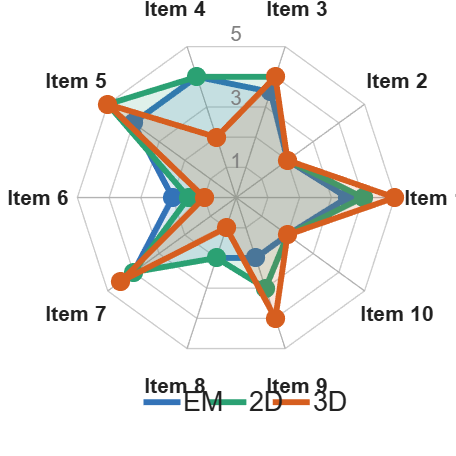

Figura guardada: nav_SUS_spider_students.pdf


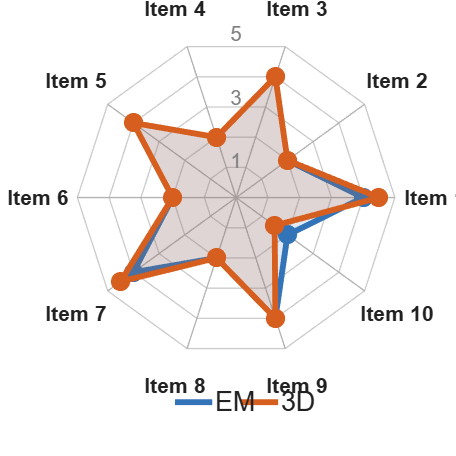

Figura guardada: nav_SUS_spider_interns.pdf



sus_item_labels = {'Item 1','Item 2','Item 3','Item 4','Item 5','Item 6','Item 7','Item 8','Item 9','Item 10'};

for gi = 1:2
    idx = group_idxs{gi};
    nd  = 10;

    if gi == 1
        keys    = {'em','x2d','x3d'};
        colors  = col_nav;
        leg_lbl = {'EM','2D','3D'};
    else
        keys    = {'em','x3d'};
        colors  = col_nav([1 3],:);
        leg_lbl = {'EM','3D'};
    end

    D = zeros(nd, numel(keys));
    for m = 1:numel(keys)
        for it = 1:nd
            col_it = SUS.(keys{m}).items(idx, it);
            col_it = col_it(~isnan(col_it));
            if ~isempty(col_it), D(it,m) = median(col_it); end
        end
    end

    fig = figure('Name',sprintf('Nav_SUS_spider_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 13 13],'Color','white');
    ax = axes(fig); hold(ax,'on');
    h_lines = draw_radar_nav(ax, D, sus_item_labels, colors, 5);

    legend(ax, h_lines, leg_lbl, 'Location','southoutside', ...
        'Orientation','horizontal','FontSize',10,'Box','off');


    fname = sprintf('nav_SUS_spider_%s.pdf',group_short{gi});
    exportgraphics(fig,fname,'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: %s\n',fname);
end



%% =========================================================
%  FUNÇÕES LOCAIS AUXILIARES
%% =========================================================

%  draw_radar_nav — radar/spider chart (idêntico ao draw_radar original)
%  data_matrix: [nd x nm]  — nd dimensões, nm métodos
%  dim_labels:  cell {nd}
%  colors:      [nm x 3]   — uma cor por método
%  max_val:     máximo da escala (5 para likert, 3 para rankings)
%  Devolve h_lines [nm x 1] para usar na legenda
function h_lines = draw_radar_nav(ax, data_matrix, dim_labels, colors, max_val)
    [nd, nm] = size(data_matrix);
    angles   = linspace(0, 2*pi, nd+1);

    % Anéis e raios de fundo
    for r = 1:max_val
        xr = r/max_val * cos(angles);
        yr = r/max_val * sin(angles);
        plot(ax,[xr xr(1)],[yr yr(1)],'Color',[0.8 0.8 0.8],'LineWidth',0.5);
    end
    for d = 1:nd
        line(ax,[0 cos(angles(d))],[0 sin(angles(d))], ...
            'Color',[0.7 0.7 0.7],'LineWidth',0.5);
    end

    % Polígonos por método
    h_lines = gobjects(nm,1);
    for m = 1:nm
        vals = data_matrix(:,m) / max_val;
        xv   = vals .* cos(angles(1:nd))';
        yv   = vals .* sin(angles(1:nd))';
        xv(end+1) = xv(1); yv(end+1) = yv(1); %#ok<AGROW>
        h_lines(m) = plot(ax,xv,yv,'Color',colors(m,:),'LineWidth',2.2);
        fill(ax,xv,yv,colors(m,:),'FaceAlpha',0.15,'EdgeColor','none');
        scatter(ax,xv(1:nd),yv(1:nd),45,colors(m,:),'filled', ...
            'MarkerEdgeColor',colors(m,:));
    end

    % Labels das dimensões
    label_r = 1.25;
    for d = 1:nd
        text(ax, label_r*cos(angles(d)), label_r*sin(angles(d)), dim_labels{d}, ...
            'HorizontalAlignment','center','FontSize',8,'FontWeight','bold');
    end

    % Labels dos anéis
    ring_vals = unique([1, round(max_val/2), max_val]);
    for r = ring_vals
        text(ax, 0, r/max_val+0.03, num2str(r), ...
            'HorizontalAlignment','center','FontSize',7.5,'Color',[0.5 0.5 0.5]);
    end

    axis(ax,'equal','off');
end

%  cond_label_to_idx — 'EM'→1, '2D'→2, '3D'→3 (sem usar struct)
function idx = cond_label_to_idx(lbl)
    lbl = strtrim(lbl);
    if     strcmp(lbl,'EM'),  idx = 1;
    elseif strcmp(lbl,'2D'),  idx = 2;
    elseif strcmp(lbl,'3D'),  idx = 3;
    else,                     idx = 0;
    end
end

%  sig_star — p-value → asteriscos
function lbl = sig_star(p)
    if p < 0.05,  lbl = '*';
    else,             lbl = 'ns';
    end
end

%  draw_sig_bracket — linha de significância entre dois pontos x
function draw_sig_bracket(ax, x1, x2, y, gap, p_bonf)
    if isnan(p_bonf) || p_bonf >= 0.05, return; end
    tk = gap * 0.25;
    line(ax,[x1 x1 x2 x2],[y-tk y y y-tk], ...
        'Color','k','LineWidth',1.3,'Clipping','off');
    if  p_bonf < 0.05,  lbl='*';
    else
    end
    text(ax,(x1+x2)/2, y+tk*0.3, lbl, ...
        'HorizontalAlignment','center','VerticalAlignment','bottom', ...
        'FontSize',10,'FontWeight','bold','Clipping','off');
end